# VSA Operators and dynamics supporting VS-BIND; an overview using a new object-oriented vector-symbolic MATLAB library

## Introduction

Within this demo, we use our own MATLAB implementation of vector symbolic operators as a tool to demonstrate of key concepts in our paper, up to and including basic dynamics. VS-BIND, our sequence processing model, is supported by pre-existing VSA operations but incorporates: novel configurations of these; site-specific neurobiological predictions integrating published findings; and additional dynamic mechanisms we touch upon in the paper but which are largely beyond the scope of this demonstration. A full implementation of VS-BIND is underway in Python's Nengo (Bekolay, 2014) as a massive-scale spiking neural network (SNN).

Although VS-BIND is intended to be simulated as a SNN, using coding principles of Eliasmith's Neural Engineering Framework and Semantic Pointer Architecture (NEF and SPA; Eliasmith, 2013) to instantiate the VSA components, we are not locked into Nengo, or the principles of the NEF, if we are agnostic about aspects of the neural implementation. We can illustrate key points in the paper by demonstrating function within the pure MATLAB implementation shown here, even with respect to aspects of dynamics; it is simply that the dynamics are ideally, not neurally, generated, and applied to cognitive vectors, rather than neural representations.

The mathematically ideal, purely cognitive approach shown here and the Nengo SNN can be used as two distinct methods of implementing the same model, as illustrated in the diagram below, which outlines VS-BIND at the implementational and cognitive levels:

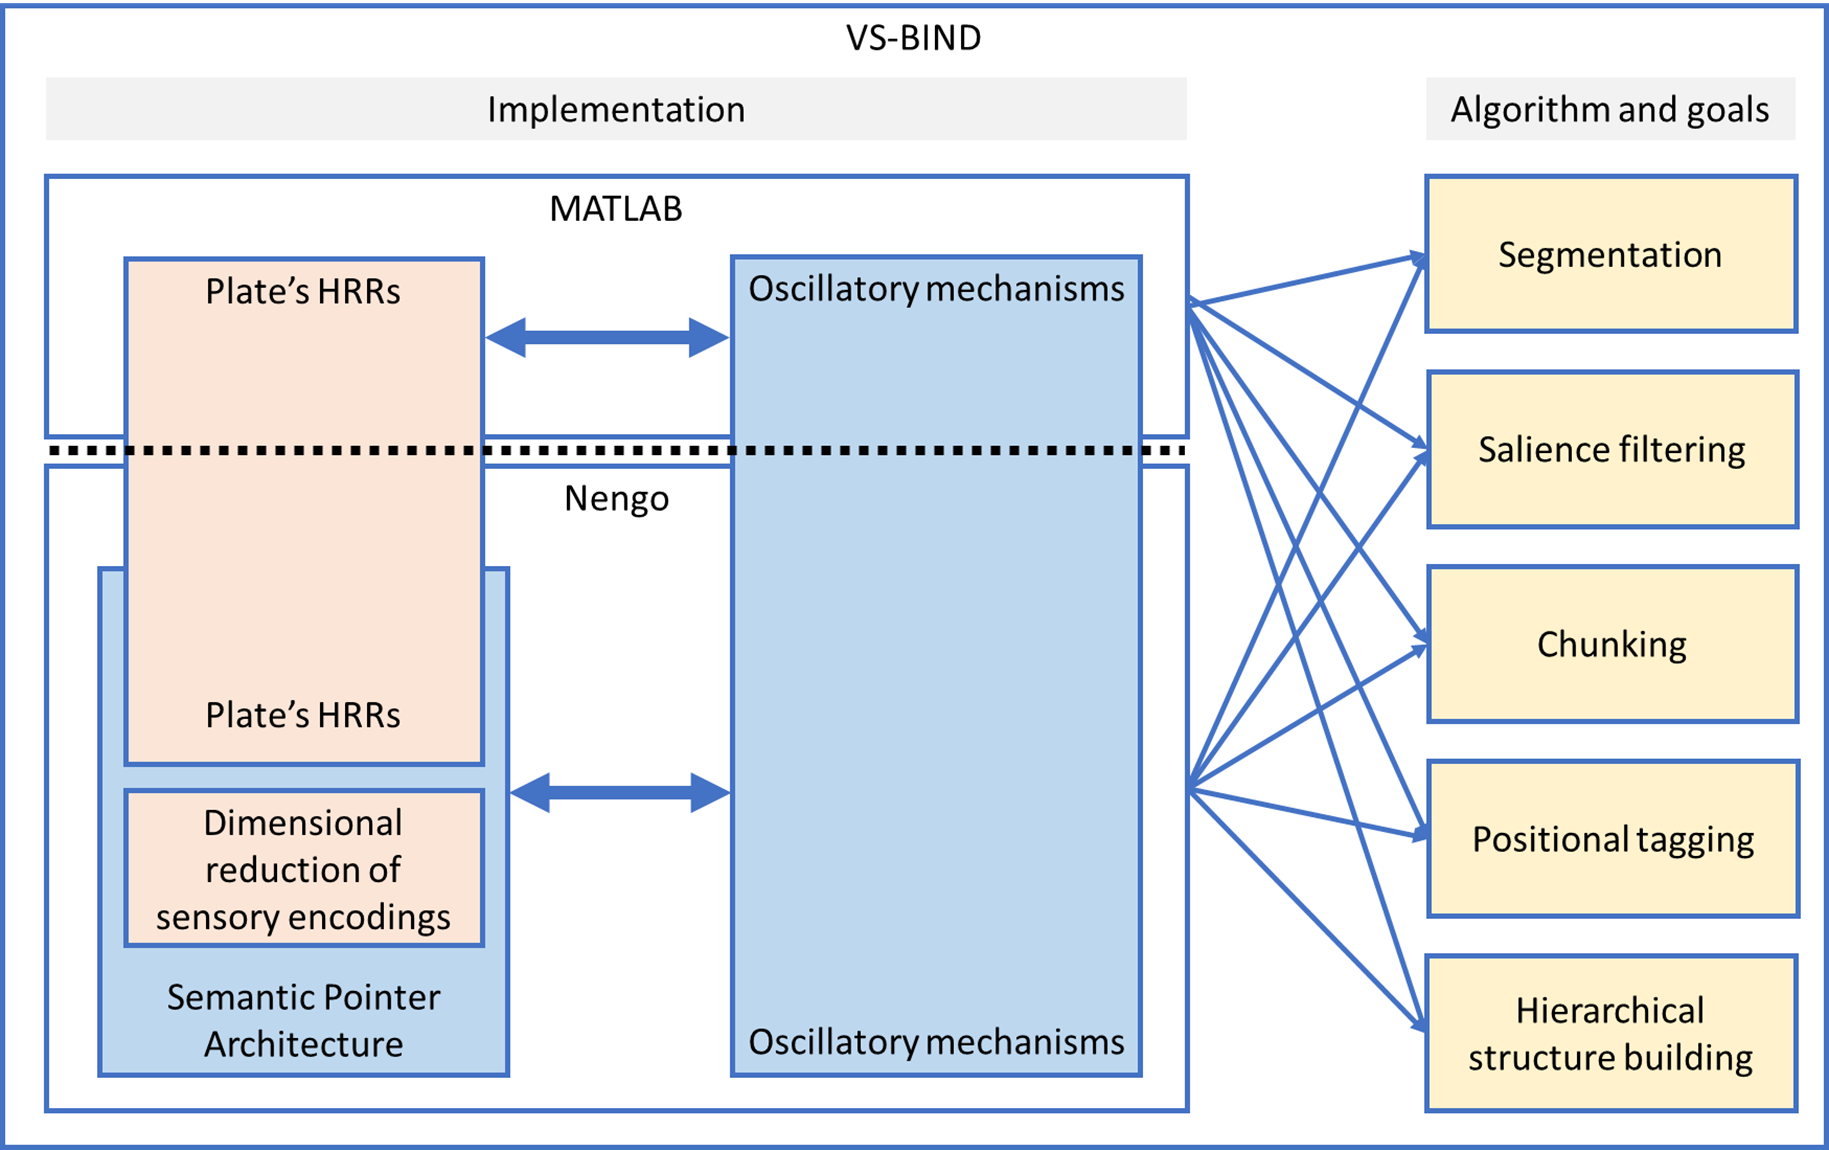

## Setup

Running this Live Script will set up the environment to use the functions in this supplementary codebase. Alternatively, the reader may manually add the "includes" folder to their path to access the functions.

addpath('includes');

## Instantiation

Using our unique vector symbolic prototyping library, random vector representations can be instantiated in MATLAB as follows.

Here, VSA representations are objects that contain a vector of features, and possess a defined dimensionality, sparsity (only used during random instantiation), name, and other properties for diagrammatic visualisation. These vectors do not instantiate neural encodings as they would within the Python-based "Nengo" (Bekolay, 2004) using the NEF, and they are likewise not inherently dynamic, but they fulfil important illustrative purposes.

These objects support a set of operators that conform to Plate's (1995) Holographic Reduced Representation architecture.

A = SymbolicVector % no closing semicolon so we can see the output in the output 

A =   SymbolicVector with properties:

                    vector: [1×4096 double]
                dimensions: 4096
                  sparsity: 0.0500
                      name: 'Unnamed VSA population'
        visualisationColor: [0.2549 0.4431 0.6118]
    visualisationLineWidth: 7


                   % panel to the right -->
B = SymbolicVector;

A.name = 'Representation A'; % we can assign to selected properties of the object, 
                             % for example the name, used in visualisation

The vector of each representation is accessible as shown here:

A.vector

ans =    -0.1511         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.0383         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.0210         0         0         0    0.0158         0         0         0


## Features and state space

What do the various features (i.e. dimensions) of a VSA representation signify? Here, we follow the approach of Eliasmith (2013) and the broad tenets of his Neural Engineering Framework (NEF), by separating the cognitive and neural levels but supporting a mapping between them. Each features is one dimension of a high-dimensional distributed code in state space, which means that they need not have any subsymbolic significance by themselves. However, *together*, all of the dimensions form a single distributed representation that can be assigned a "symbolic" meaning.

To put it another way, each vector represents a concept at the cognitive level. Negative and positive feature values are permissible in any individual dimension because these do not represent neural firing rates directly. However, they can be mapped to them using something like the NEF (Put simply, the NEF in part proposes that any given neuron will fire maximally to a specific high dimensional vector, a *preferred direction vector*, firing proportionally to the dot product between a given high-dimensional representation and the preferred direction; thus, a sufficiently sized population of differently tuned neurons can collectively allow high-fidelity encoding of a cognitive vector representation).

## Combination and comparison

We express superposition, binding, inversion and any other required operators by co-opting MATLAB's standard arithmetic notation for ease of use.

Here, superposition is expressed as

SomeSuperposition = A+B;

binding as

SomeBinding = A*B % we can see the output of this statement due to lack of semicolon -->

SomeBinding =   SymbolicVector with properties:

                    vector: [1×4096 double]
                dimensions: 4096
                  sparsity: 0.0500
                      name: 'Unnamed VSA population'
        visualisationColor: [0.2549 0.4431 0.6118]
    visualisationLineWidth: 7


involution/inversion as

SomeInverse = ~A;

Note that all the operators above return a new high-dimensional vector but that only the output of line 4 is shown for brevity.

The calculation of similarity (comparison) between two vectors is performed using the equality ("==") operator, and returns a scalar, where 1 represents the highest level of similarity and, as with correlation coefficients, negative values are possible.

It can be seen that random vectors have low similarity (they are approximately orthogonal; *results may vary each run*).

Similarity = A==B;
fprintf('The similarity of A and B is %f\n',Similarity);

The similarity of A and B is -0.001260


## Visualisation

We can visualise each vector in a number of ways.

Firstly, let us view the raw vector (for ease of visual comparison, these are rendered as square representations created by reshaping the underlying vector):

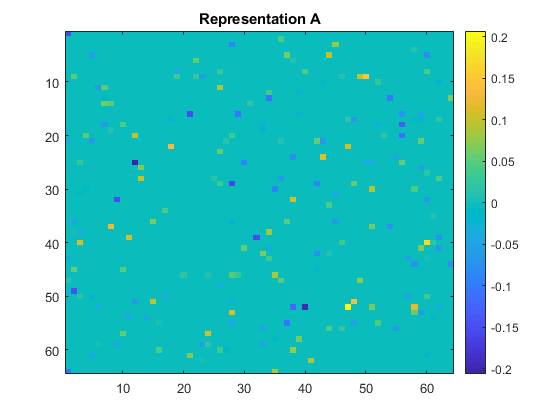

plot(A); % A.plot would also work identically

You should see something like:

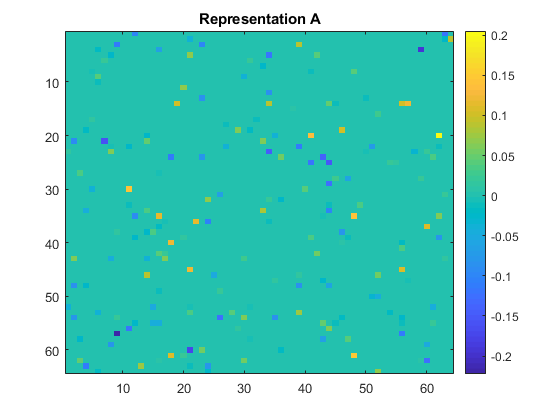

### Superposition results

Using this plotting function enables us to see by eye that superposing A and B results in a similar representation to A:

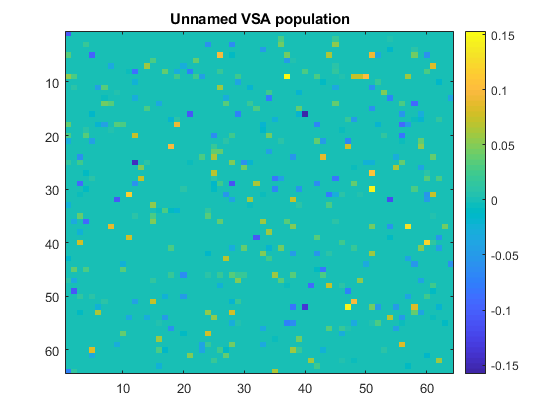

plot(A+B);

You should see something like:

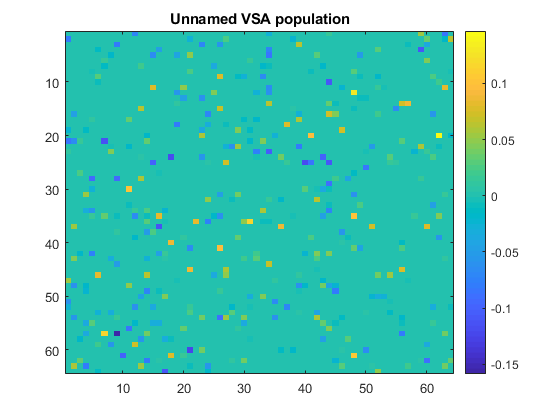

In fact, the superposed representation is similar to both A and B, which we can prove by using the comparison operator:

A == (A+B); % we don't have to store comparison results; here MATLAB stores it in for us
fprintf('The similarity of A and A+B (superposition) is %f\n',ans);

The similarity of A and A+B (superposition) is 0.706718


fprintf('The similarity of B and A+B (superposition) is %f\n',B == (A+B)); % use directly

The similarity of B and A+B (superposition) is 0.706605


### Binding results

Now we can do likewise for binding. We first store this new binding as NewBinding just to demonstrate that operations are deterministic, then compare the binding result to the constituents:

NewBinding = A*B;

Comparison1 = (A == A*B); % here, we compare A to a newly calculated result
Comparison2 = (A == NewBinding); % here, we compare A to the stored result

fprintf(['Comparison1 is %f and Comparison2 is %f, showing our binding result is ',...
     'deterministic.\n'],Comparison1,Comparison2);

Comparison1 is -0.025709 and Comparison2 is -0.025709, showing our binding result is deterministic.



fprintf(['The similarity of A and A*B (binding) is %f. This should be a value close to',...
    ' zero\nsince bindings are orthogonal to their inputs.\n'],(A==A*B));

The similarity of A and A*B (binding) is -0.025709. This should be a value close to zero
since bindings are orthogonal to their inputs.



B == NewBinding; % here, we compare B to the stored result

fprintf(['The similarity of B and A*B (binding) is %f. This should also be a low value\n',...
  'since bindings are orthogonal to both inputs.\n'],ans); % print the most recent result

The similarity of B and A*B (binding) is -0.160406. This should also be a low value
since bindings are orthogonal to both inputs.


Let us plot A again and compare it visually to the binding of A and B. The two will look very different:

plot(A);

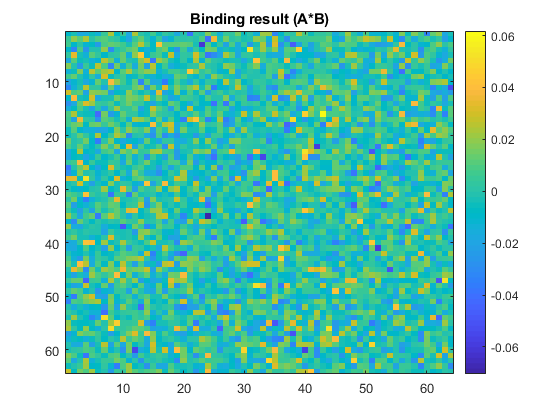

NewBinding.name = 'Binding result (A*B)';
plot(NewBinding);

### Unbinding

Let us do all the operations in sequence. We can calculate a binding of A and B and then unbind it using the inversion operator as follows:

NewBinding = A*B;
UnbindingResult = NewBinding * ~B;
UnbindingResult.name = 'Unbound result';

Here, we have bound A*B with the inverse of a key, B. We expect that using this key, we should recover the other constituent - i.e. something similar to A...

fprintf(['The similarity of the unbinding to A is %f and the similarity ',...
    'to B is %f\n'],UnbindingResult==A,UnbindingResult==B)

The similarity of the unbinding to A is 0.706033 and the similarity to B is -0.014719


...which it is.

Why isn't it completely identical to A (i.e. why not a similarity of 1)? We can compare A and B side by side and find out:

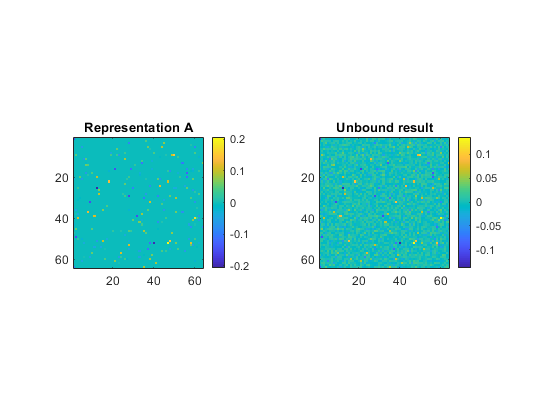

subplot(1,2,1);
newplot = plot(A); % (we can quickly suppress creation of new figure by assigning
                   % the output of the plot function)
axis square
subplot(1,2,2);
newplot = plot(UnbindingResult);
axis square

Now it can be seen that A and the unbound representation are not identical due to noise in the lossy decoding of A. This can be overcome using the comparison operator to choose those representations more similar than a set threshold and instead produce the superposotion of matching representations as output (a simple cleanup memory; Crawford, 2014). There is a pre-existing non-neural implementation of this we can quickly use to test the concept as follows:

UnbindingResult = UnbindingResult.cleanup(A,B); % we provide a vocabulary of 
                                                % vectors (here A,B) and clean up
                                                % the result by matching with them
fprintf(['By cleaning up the result, we obtain a vector with %f similarity to A',...
       ' and %f similarity to B\n'], UnbindingResult==A,UnbindingResult==B);

By cleaning up the result, we obtain a vector with 1.000000 similarity to A and -0.001260 similarity to B


### Vectors as directions in high-dimensional space

As well as being lists of numbers, these vectors can be considered directions and magnitudes in high-dimensional space. High-dimensional space is very difficult to visualise so the code here provides a function that uses Principle Components Analysis to map the vectors down to three dimensions:

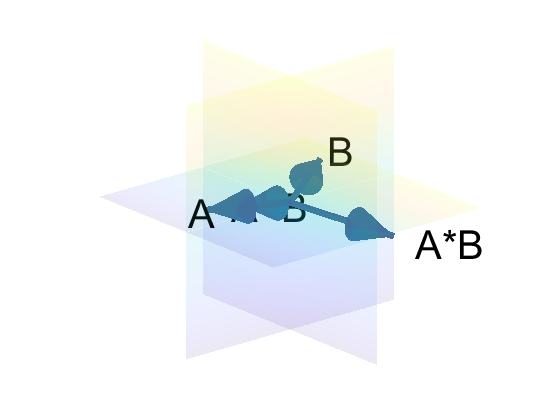

plot3d([A,B,A+B,A*B],{'A','B','A+B','A*B'}); % plot four HD vectors relative to each

                                             % other in 3D space by embedding using PCA

*Click on the image in the output pane and click on the "open in figure window" icon to show the figure and allow rotation in 3D.*

Using this approach, it can be seen that central tenets which hold in 3 dimensions also hold for these high-dimensional vectors, namely that addition produces vectors facing in an intermediate direction and that binding through circular convolution produces an orthogonal vector much like a cross product at this level.

## Sequence structure

### Positional tagging

We can now represent a sequence by defining position tags and items as follows:

X = SymbolicVector;

First = SymbolicVector;
Second = SymbolicVector;
Third = SymbolicVector;
Fourth = SymbolicVector;

Sequence = A*First + X*Second + X*Third + B*Fourth; % The sequence "AxxB"

Using the comparison operator repeatedly by hand can be unwieldy, so instead we can use a function that compares multiple vectors at once and plots the result. Let us compare the sequence to its constituents. It can be seen that they are dissimilar.

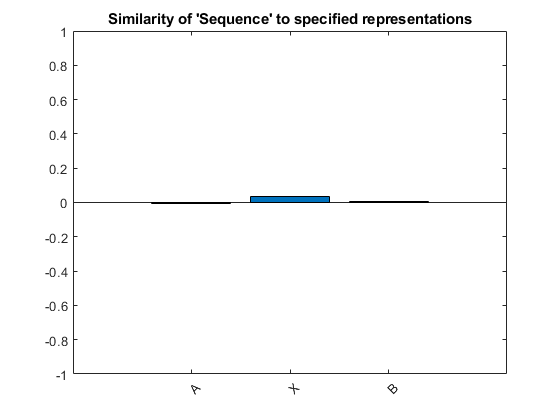

compareAll(Sequence, A,X,B);

Now let us unbind the sequence using a tag and compare the result to the constituents. We seek the first item, and so the result should be most similar to "A"...

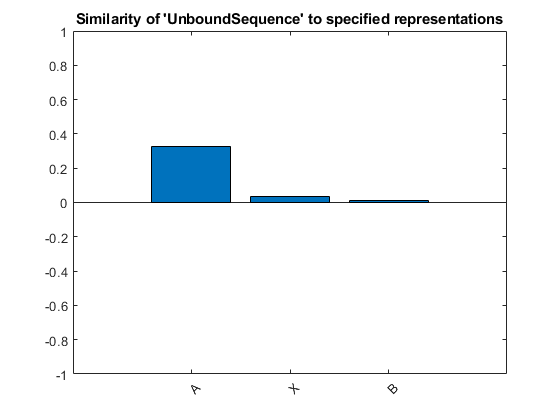

UnboundSequence = Sequence*~First;

compareAll(UnboundSequence, A,X,B);

...as it is.

### Chunking

We can apply a mechanism more similar in essence to that used by VS-BIND (but lacking spiking neural instantiation, oscillator-driven, boundary relative encodings and details of the network-network interactions that make this possible in dynamic terms) by encoding serial input in terms of chunks, manually defining new tags for not just items but also chunks as well (here encoding a sequence equivalent to **Figure 3,** **right diagram** of the paper, where the chunks are constructed from discontiguous elements):

% Item tags
I1 = SymbolicVector;
I2 = SymbolicVector;

% Chunk tags
C1 = SymbolicVector;
C2 = SymbolicVector;

% Items
A1 = SymbolicVector;
A2 = SymbolicVector;
B2 = SymbolicVector;
B1 = SymbolicVector;

Sequence = C1 * (I1 * A1 + I2 * B1) + C2 * (I1 * A2 + I2 * B2);

Again, let us unbind the sequence using tags and compare the result to the constituents. We now seek the second item of the first chunk, and so the result should be most similar to "B1"...

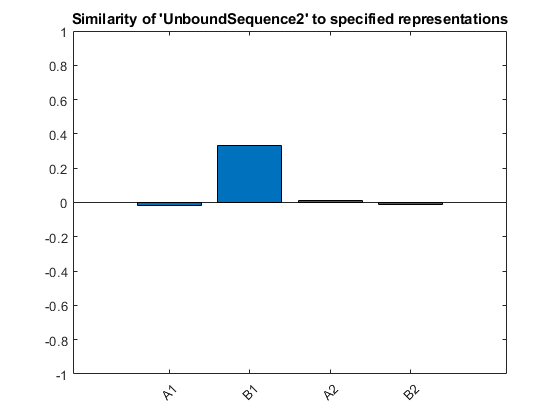

UnboundSequence2 = Sequence*~(C1 * I2);

compareAll(UnboundSequence2, A1,B1,A2,B2);

...as it is. We can undertake the same again, this time for the first item of the second chunk, which should return a result similar to "A2":

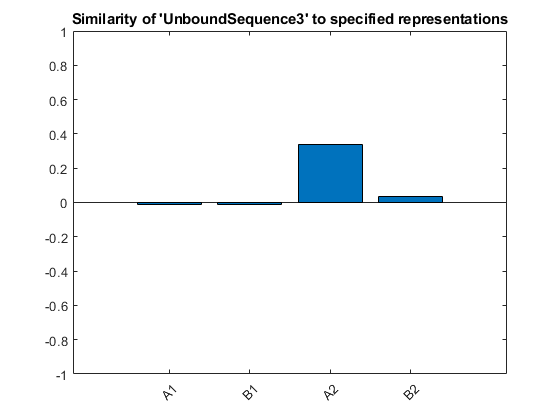

UnboundSequence3 = Sequence*~(C2 * I1);

compareAll(UnboundSequence3, A1,B1,A2,B2);

Note that performance on short sequences is not yet compromised even without the added benefit of a cleanup memory.

Using the below approach, we may also extract the entire first chunk:

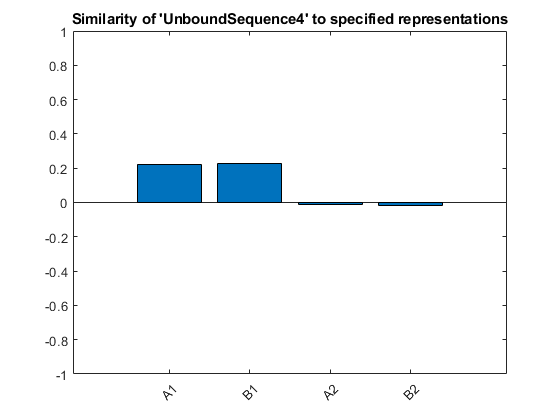

UnboundSequence4 = Sequence * ~(C1 * (I1 + I2));

compareAll(UnboundSequence4, A1,B1,A2,B2);

Or the second item of all chunks:

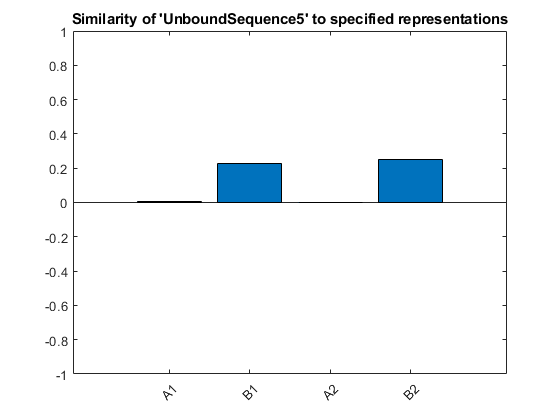

UnboundSequence5 = Sequence * ~((C1 + C2) * I2);

compareAll(UnboundSequence5, A1,B1,A2,B2);

To enhance the above approach, we can also apply a more general position encoding mechanism, used within some existing VSA models, by expressing position in terms of convolutional powers (e.g. The third position is given by P * P * P is expressed as P^3). We use this approach in subsequent code. 

### Centre embedded and Crossed ("cross-serial") dependencies

We have seen how sequences may be conceived of as chunks, and how this can support encoding of structure within sequences, but we have not demonstrated how they might be derived from sequentially unfolding, linear input.

Now let us look more closely at more plausible encoding and decoding of sequencing dependencies. The code below illustrates a system in which sequences are first *linearly *encoded within a region such as SMA, which here acts as a sequence buffer, and then recoded by VLPFC into chunks:

%Item tags
I = SymbolicVector;

%Chunk tags
C = SymbolicVector;

%Items
A1 = SymbolicVector; A1.name = 'A1';
A2 = SymbolicVector; A2.name = 'A2';
B2 = SymbolicVector; B2.name = 'B2';
B1 = SymbolicVector; B1.name = 'B1';

Vocabulary = {A1,A2,B2,B1}; % a list of encountered vocabulary vectors for the cleanup memory to match to

% An incoming sequence encoded linearly using position information ("I" raised
% to a convolutional power)
SequenceBuffer_SMA = I^1 * A1 + I^2 * A2 + I^3 * B2 + I^4 * B1; % store a linear encoding of "A1 A2 B2 B1"

% Recode sequence in terms of nested dependencies:

Dependency1_VLPFC = I^1 * cleanup(SequenceBuffer_SMA * ~I^1,Vocabulary{:}) ...
            + I^2 * cleanup(SequenceBuffer_SMA * ~I^4,Vocabulary{:});
              
Dependency2_VLPFC = I^1 * cleanup(SequenceBuffer_SMA * ~I^2,Vocabulary{:}) ...
            + I^2 * cleanup(SequenceBuffer_SMA * ~I^3,Vocabulary{:});
        
DependencyBuffer_VLPFC = C^1 * Dependency1_VLPFC + C^2 * Dependency2_VLPFC;

DecodedOuterNestedDependency = DependencyBuffer_VLPFC * ~(C^1 * (I^1 + I^2));
DecodedOuterNestedDependency = DecodedOuterNestedDependency.cleanup(A1,A2,B1,B2)

DecodedOuterNestedDependency =   SymbolicVector with properties:

                    vector: [1×4096 double]
                dimensions: 4096
                  sparsity: 0.0500
                      name: 'Unnamed VSA population'
        visualisationColor: [0.2549 0.4431 0.6118]
    visualisationLineWidth: 7


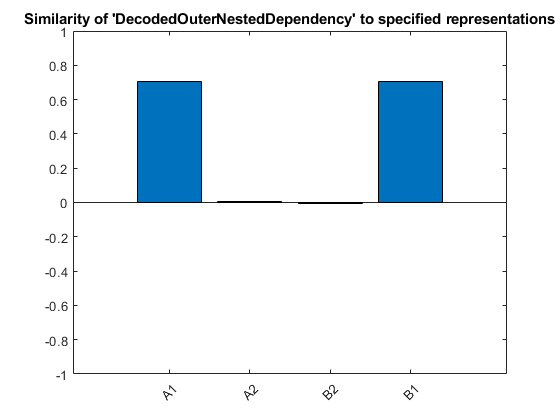

compareAll(DecodedOuterNestedDependency,Vocabulary{:});

Here, after recoding the linear sequence "A1 A2 B2 B1", the implicit structure of the dependency relationships is "[A1 [A2 B2] B1]". The chart on the right shows that one chunk now contains both "A1" and "B1", and displays the elements in temporal order to demonstrate the location of those elements in the original sequence. This same mechanism can also describe two crossed dependencies (here we encode and decode the first crossed dependency only):

SequenceBuffer_SMA = I^1 * A1 + I^2 * A2 + I^3 * B1 + I^4 * B2; % store a linear encoding of "A1 A2 B1 B2"

Vocabulary = {A1,A2,B1,B2};

% Recode sequence in terms of crossed dependencies:

Dependency1_VLPFC = I^1 * cleanup(SequenceBuffer_SMA * ~I^1,Vocabulary{:}) ...
             + I^2 * cleanup(SequenceBuffer_SMA * ~I^3,Vocabulary{:});
         
Dependency2_VLPFC = I^1 * cleanup(SequenceBuffer_SMA * ~I^2,Vocabulary{:}) ...
             + I^2 * cleanup(SequenceBuffer_SMA * ~I^4,Vocabulary{:});
         
DependencyBuffer_VLPFC = C^1 * Dependency1_VLPFC + C^2 * Dependency2_VLPFC;

DecodedFirstCrossedDependency = DependencyBuffer_VLPFC * ~(C^1 * (I^1 + I^2));
DecodedFirstCrossedDependency = DecodedFirstCrossedDependency.cleanup(A1,A2,B1,B2)

DecodedFirstCrossedDependency =   SymbolicVector with properties:

                    vector: [1×4096 double]
                dimensions: 4096
                  sparsity: 0.0500
                      name: 'Unnamed VSA population'
        visualisationColor: [0.2549 0.4431 0.6118]
    visualisationLineWidth: 7


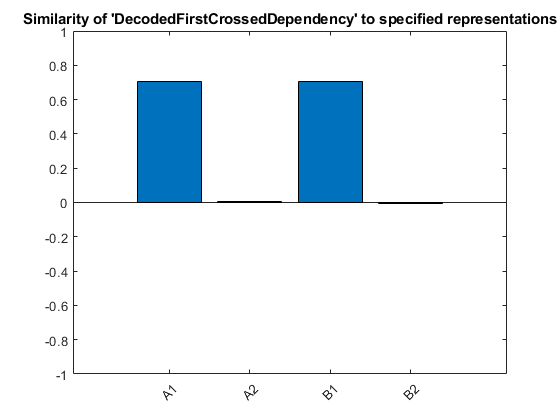


compareAll(DecodedFirstCrossedDependency,Vocabulary{:});

This demonstrates that a buffered representational scheme is capable of accounting for centre-embedded as well as cross-serial dependencies. Evidently this account offers evidence of appropriate representational capabilities, but does not address other critical topics; implicit learning, and the mechanisms for the online application of learned structure, are vital components also under consideration within VS-BIND, but beyond the scope of this particular demo.

## Dynamics

Here, using a custom-coded MATLAB framework for prototyping VSA algorithms, we have illustrated the general principles underlying Plate's VSA, produced visualisations demonstrating core operations and configurations of operations, and established basic principles of the chunk encoding used in VS-BIND. Implementation of more advanced characteristics of the model are beyond the scope of this walkthrough, but before we finish, we broadly illustrate how dynamics can be used to coordinate vector symbolic operations.

Here, we describe an oscillatory signal over time, without neurons, and then use its amplitude, as well as a temporary buffer ("StoredValue", which may be implemented using integrating circuits in a spiking neural framework such as Nengo) to control binding with a new and constantly changing random vector. Thus, we change a vector at discrete intervals controlled by the period of the oscillator.

After a threshold is reached, the "stored value" population effectively provides a negative feedback signal to prevent continous binding from occurring throughout the suprathreshold period, and then transfers its result back out when the instantaneous value of the oscillator signal dips below the threshold again. Obviously, there are many ways in which this fails to perfectly represent the functioning of a viable neural system, but the discretising and coordinating function of oscillators, principles essential to VS-BIND and applied extensively within our currently developing Nengo implementation, should be clear from the output of the code below, which renders an oscillatory signal and, below it, at periodic intervals, the current state of a vector over time:

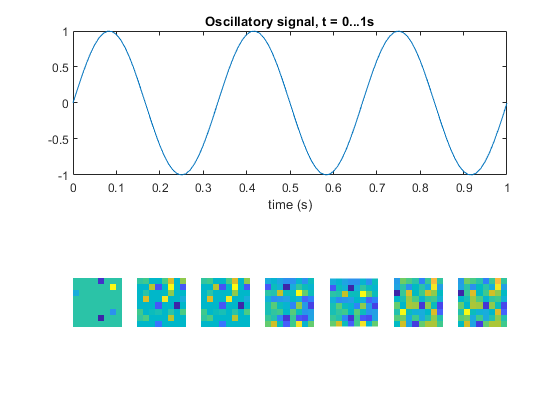

dimensions = 64; % here we specify relatively low dimensionality
sparsity = 0.1;  % and high sparsity, for ease of visualisation

SomeVector = SymbolicVector(dimensions,sparsity);
StoredValue = SomeVector;

t = 0:0.01:1; % vector of times from 0 to 1 seconds
freqHz = 3; % 3 Hz oscillator
numPlots = 7; % sample vector at 6 points in time

% Plot a low frequency oscillatory signal
subplot(2,numPlots,[1:numPlots]);
oscillatorySignal = sin(t*freqHz*2*pi);
plot(t,oscillatorySignal);
xlabel('time (s)');
title('Oscillatory signal, t = 0...1s');

currentResultPlot = 1;
plotTimes = linspace(0,t(end),numPlots);     % the times at which to plot a representation
                                             % of SomeVector (a select few, but the vector is 
                                             % continuously updated)

for indexT = 1:length(t)
    currentT = t(indexT);
    
    if oscillatorySignal(indexT) > 0.9       % For as long as an oscillator exceeds a
                                             % threshold,
         if (StoredValue == SomeVector)>0.9        % Only if some representation-maintaining
                                                   % population and SomeVector are similar
                                                   % then produce and maintain new binding 
                                                   % between SomeVector and a random vector:
             StoredValue = SomeVector * SymbolicVector(dimensions,sparsity); 
         end
    else
        SomeVector = StoredValue;            % and only when signal below threshold again, 
                                             % transmit stored value to SomeVector
    end
    
    if currentT >= plotTimes(currentResultPlot)
        subplot(2,numPlots,numPlots+currentResultPlot);
        aPlot = plot(SomeVector);
        title('');
        colorbar off;
        axis square;
        axis off;
        currentResultPlot = currentResultPlot+1;
    end
end

Note that changes in the vector representation occur at set intervals dictated by the oscillator frequency.

## Manuscript Figures

Two pre-written scripts generate diagrams central to the figures in the paper.

The first shows the concepts above in a single diagram. Run the following at the MATLAB console to display a new figure. You will need to manually resize the width of the figure by dragging your mouse to display items clearly:

The second shows the general configuration of VSA (but not oscillatory) operations in VS-BIND. Run the following at the MATLAB console to display three new figures. You will need to manually resize the width of the figures by dragging your mouse to display items clearly:

in one figure (click the image in the output pane and click on the "open in figure window" icon to resize; manually resize the figure until the scales are correct):